# SC42025 Filtering & Identification

**PRACTICAL ASSIGNMENT II**

**Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf'). Hand in one report per group before the deadline.**

**DEADLINE**: 

## Introduction

In this practical assignment you will use your model-estimation code from Homework Assignments 3 & 4  to identify an unknown system by going through the system identification cycle. For this, you need the file `exciteSystem.p`, which you can find on Brightspace. Note that this file requires the `System Identification Toolbox. `You may consider this file as an **unknown black box system**. You can provide an input sequence and a sampling frequency to this system and it will return a corresponding output sequence at the specified sampling frequency.

The file is used by adding it to your path in MATLAB and calling the function

`y = exciteSystem(STUDENTID,u,fs)`

Here, `y` is the output sequence $$y_k$$ of the to be identified system, `STUDENTID` is the **lowest-valued** student-id of the students in the group, `u` is the provided input sequence $u_k$, and` fs` is the sampling frequency. 

The system is inherently simulated in discrete time, so there is **no need for you to apply a band-pass filter to prevent anti-aliasing**, as you need to do for analog systems that have been sampled digitally. Your objective is to identify a model for this black box system. Try to determine a model that performs well on both your identification as your validation data set in terms of simulation.

It can be expected that non-Gaussian sensor noise (noise spikes) will be present in the output. These spikes need to be removed from the data before identifying the system. 

Your system may also contain a time delay. This should also be taken into account before using your identification code.

To complete this assignment, we expect you to go trough the identification cycle, see the figure below, as many times as needed.

*Throughout this practical assignment, remember that the identification cycle is an iterative process and you typically need more than one iteration. Limit your report to the final iteration.*

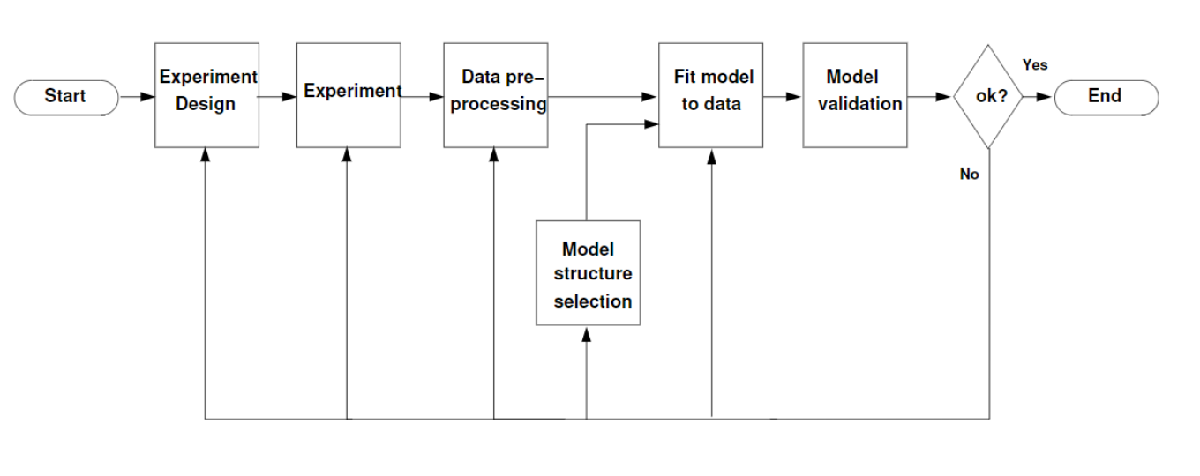

## Part 0: Setup

Please insert your names and student numbers below.

Name: Josephine King

Student Number: 6250513

Name: Thomas Prins 

Student Number: 5885221

% Clear workspace
clearvars; clc; close all;

% Insert the lowest-valued student-id of the students in the group;
STUDENTID = 5885221;

## Part 1: Experiment Design and Data Pre-Processing

The first steps of the identification cycle are to design your experiment and pre-process the input and output data. In this exercise, use the `exciteSystem` function to determine a suitable sampling frequency and motivate your answer.

*Answer**:*

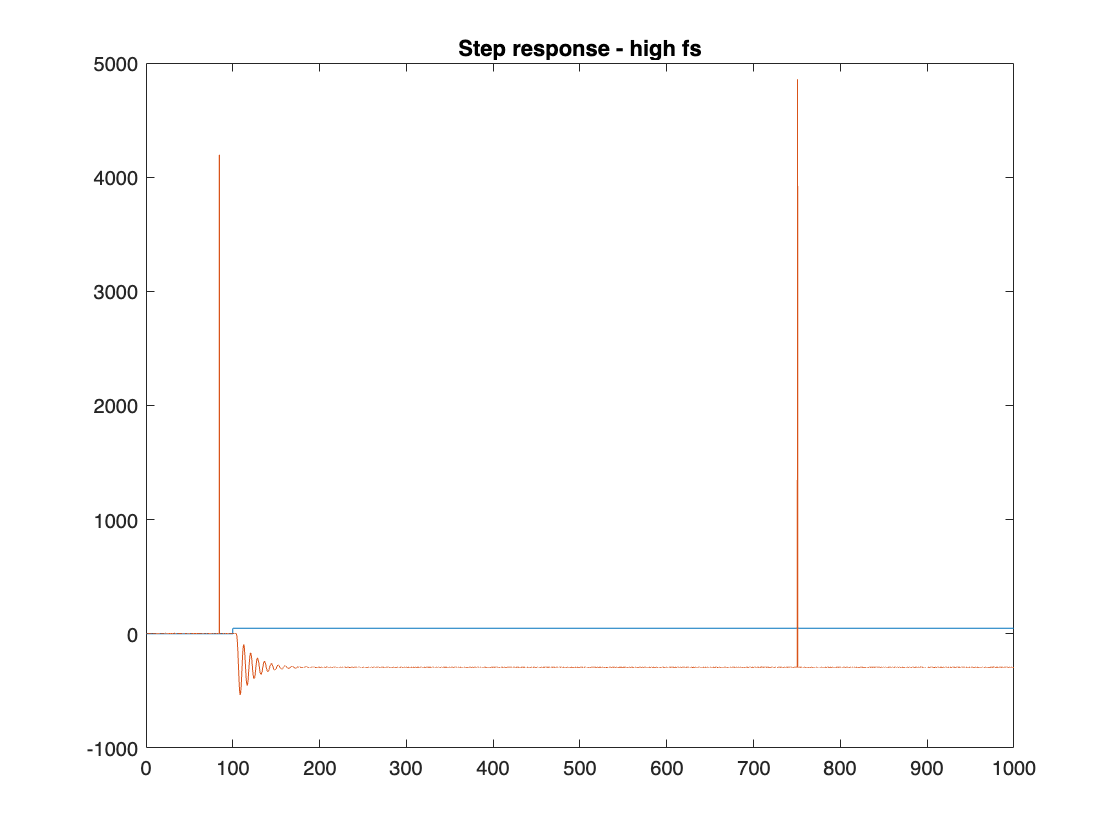

T = 1000;
fs = 10;
N = round(T*fs);
input_mag = 50;
step_start = round(N/10);
t = (1/fs)*(0:N-1);

u_step = input_mag*ones(1,N);
u_step(1:step_start) = 0;
y_step = exciteSystem(STUDENTID,u_step,fs);

plot(t,u_step,t,y_step)
title("Step response - high fs")

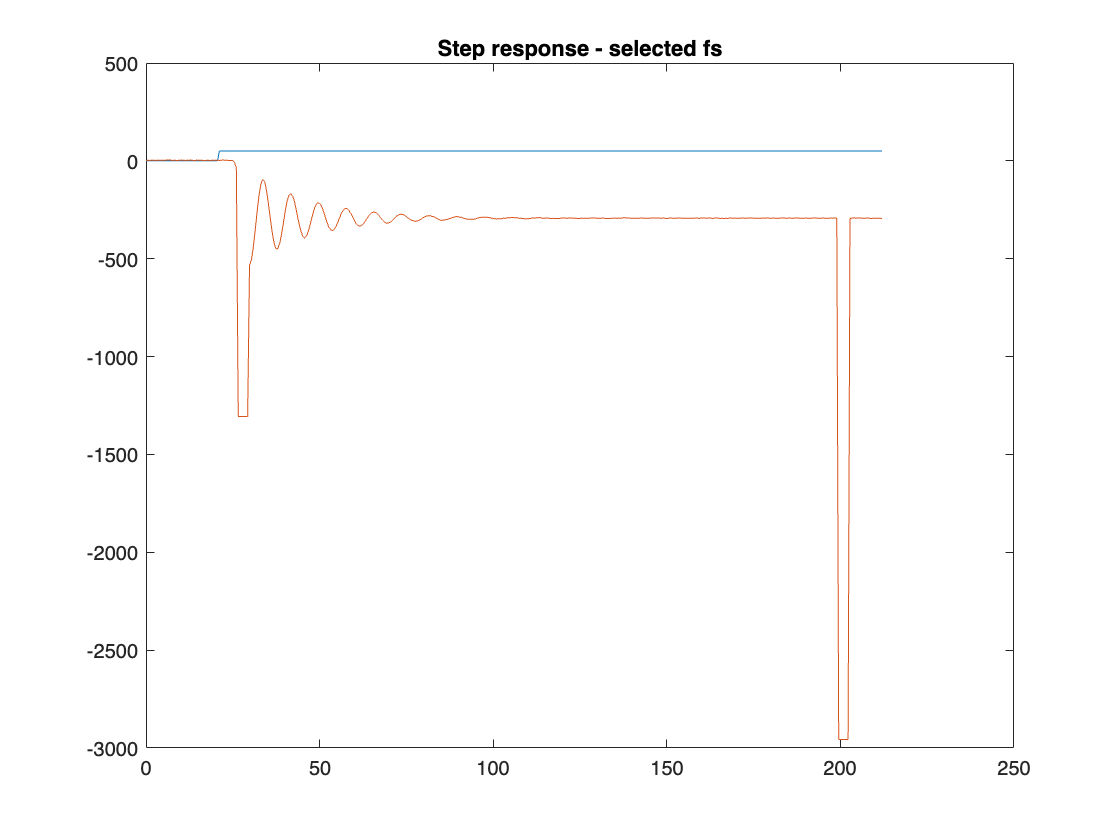


% Find the natural frequency from the time constant tau
t_cycle = 32.6 - 24.2; % duration of cycle
wn = 2*pi/t_cycle;
% Find the damping ratio from the overshoot
Mp = (533 - 292.8)/292.8;
dr = -log(Mp)/(sqrt(pi^2+(log(Mp))^2));

% Get bandwidth 
wb = wn*sqrt(1-2*dr^2+sqrt((2*dr^2-1)^2+1));
% Get sampling frequency
fs = 10*wb/(2*pi);

% Get duration from 10x time constant
tau = 1/(wn*dr);
T = 10*tau;

% Plot again with selected sampling frequency
N = round(T*fs);
t = (1/fs)*(0:N-1);
step_start = round(N/10);

u_step = input_mag*ones(1,N);
u_step(1:step_start) = 0;
y_step = exciteSystem(STUDENTID,u_step,fs);

plot(t,u_step,t,y_step)
title("Step response - selected fs")

Design a persistingly exciting input signal. Show how you determined the order of persistency of excitation.  Furthermore, you are **not allowed** to use a white-noise sequence as an input signal, as this is often not possible in the real-world.

*Answer**:*

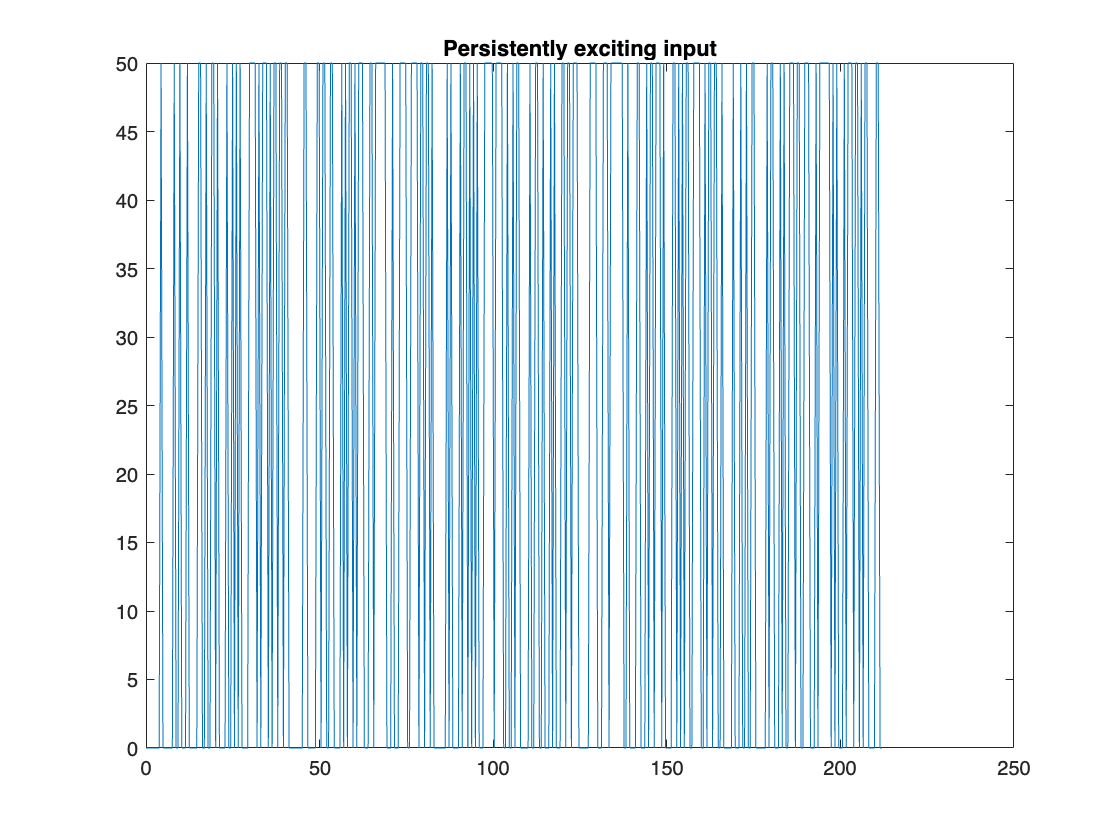

% Use MATLAB's chirp function to create a frequency sweep
u = input_mag.*prbs(10,N);
y = exciteSystem(STUDENTID,u,fs);

plot(t,u)
title("Persistently exciting input")

Motivate how you identify and remove spike noise from your data.*You may use the Matlab function *`interp1`* to do the interpolation. *Plot a figure of the output signal before and after spike removal.

*Answer**:*

y_clean = clean_y(y, input_mag);

figure(1)
plot(t,y_clean,t,y)
legend("cleaned output data", "original output data")

y = y_clean;

Determine any time-delays of your system. Correct the input and output data to account for the determined time-delay by introducing an appropriate time-shift.

*Answer**:*

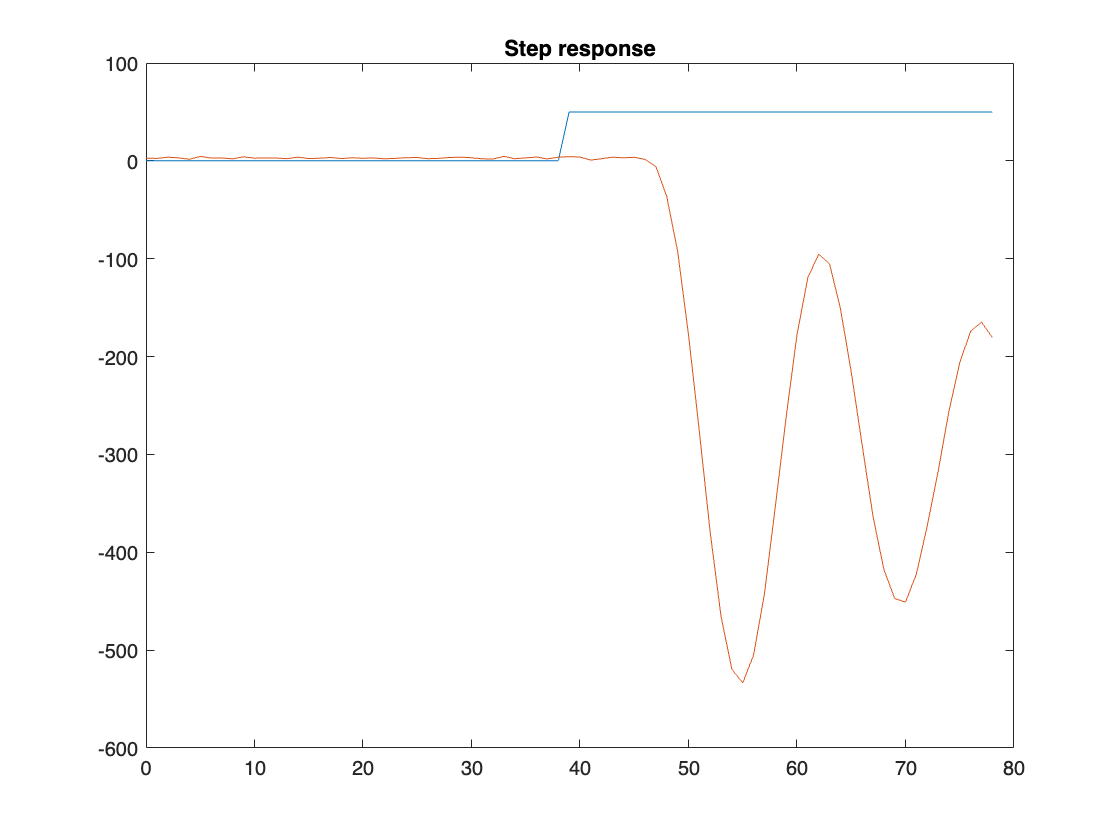

y_step = exciteSystem(STUDENTID,u_step,fs);
y_step = clean_y(y_step, input_mag);

plot(0:round(N/5),u_step(1:round(N/5)+1),0:round(N/5),y_step(1:round(N/5)+1))
title("Step response")

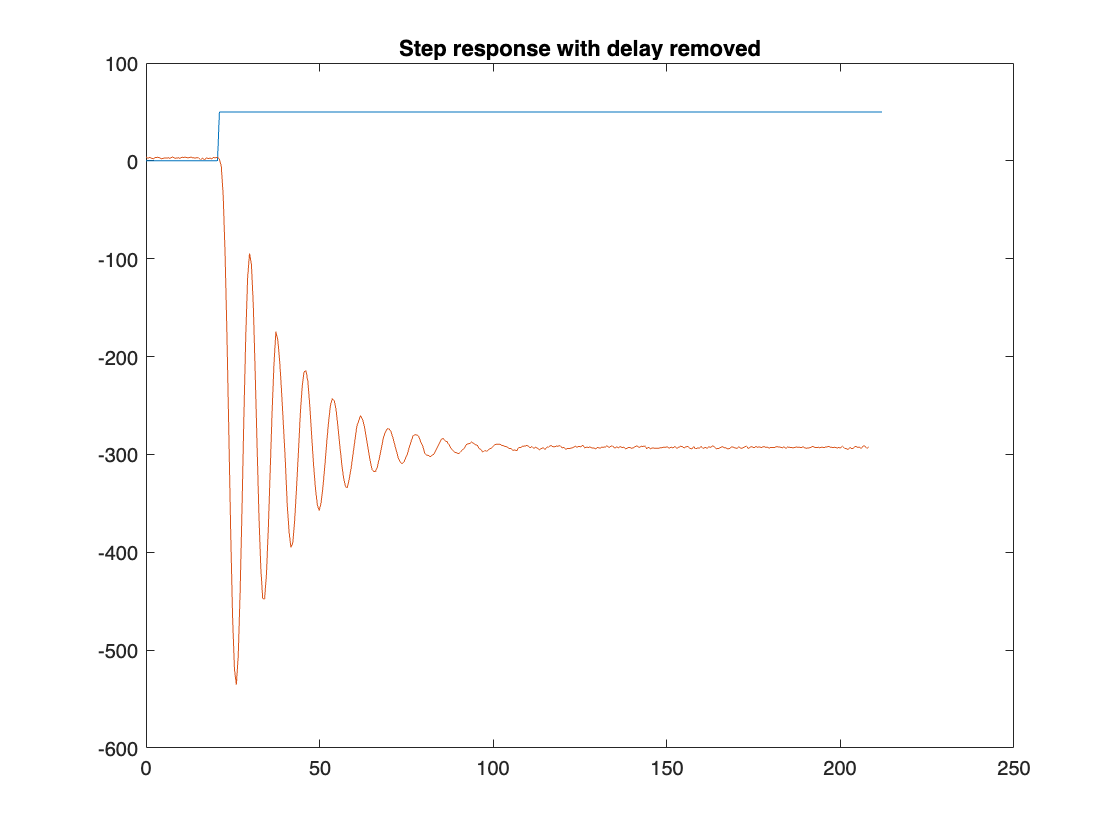


% Step response starts at time step 38, see response start at time step 46
delay = 46 - 38;
plot(t,u_step,t(1:end-delay+1),y_step(delay:end))
title("Step response with delay removed")


y = remove_delay(y, delay);
t_minus_delay = t(1:end-delay+1);


Remove the DC offset from the output (if any).

*Answer**:*

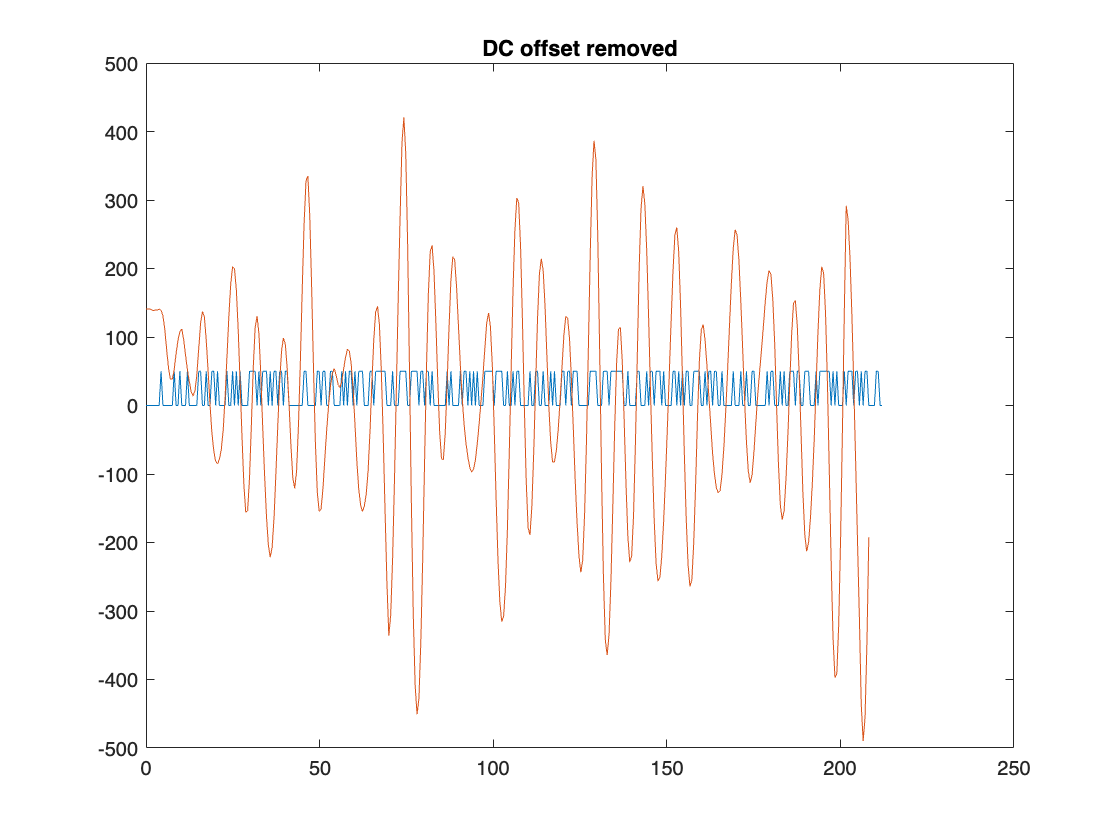

y = remove_dc_offset(y);

figure(1)
plot(t,u,t_minus_delay,y)
title("DC offset removed")

Determine whether your system is (approximately) linear by means of an experiment. Plot a figure of the experiment that you used and use this figure to motivate your conclusions.

*Answer**:*

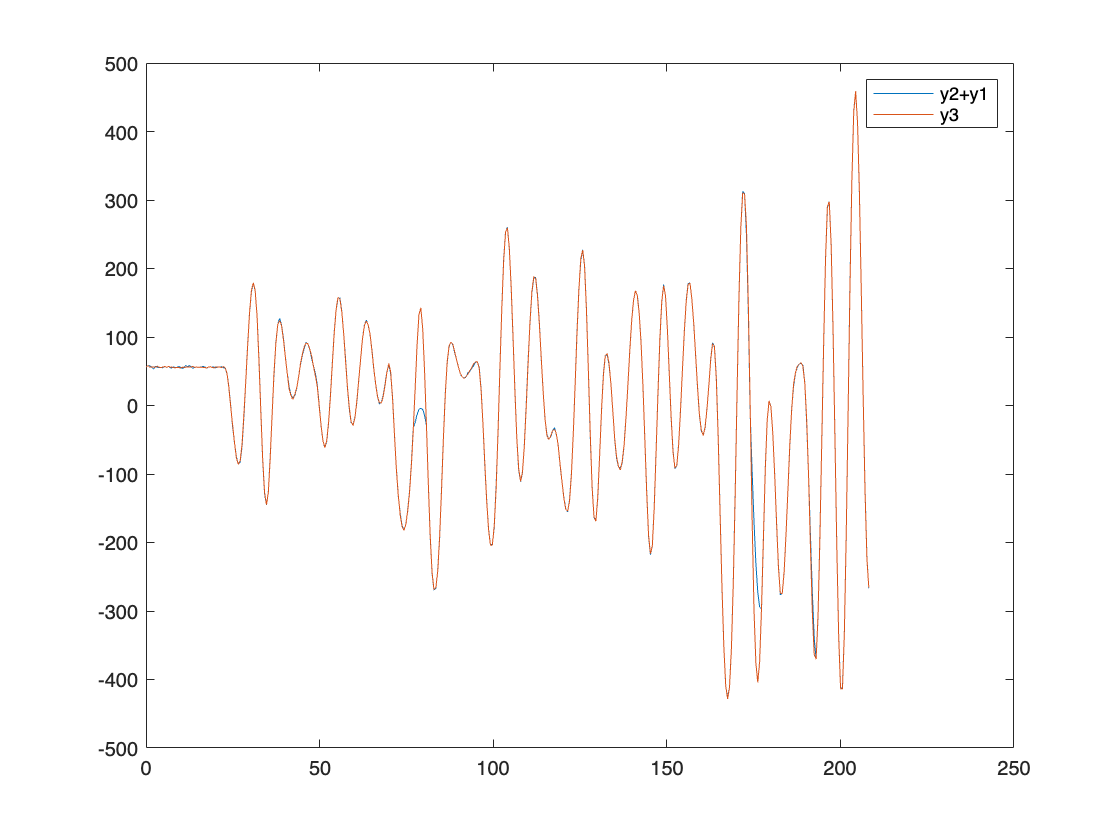

k1 = round((100-11)*rand+11);
k2 = round(10*rand+2);
u_long = input_mag.*prbs(k1,2*N);
u1 = u_long(1:N);
u2 = u_long(N+1:end);

tolerance = 1e-2;
y1 = filter_y(exciteSystem(STUDENTID,u1,fs), delay, input_mag);
y2 = filter_y(exciteSystem(STUDENTID,u2,fs), delay, input_mag);
y3 = filter_y(exciteSystem(STUDENTID,u2+u1,fs), delay, input_mag);
y4 = filter_y(exciteSystem(STUDENTID,k2*u1,fs), delay, 5*input_mag);

plot(t_minus_delay,y2+y1,t_minus_delay,y3)
legend(["y2+y1", "y3"])

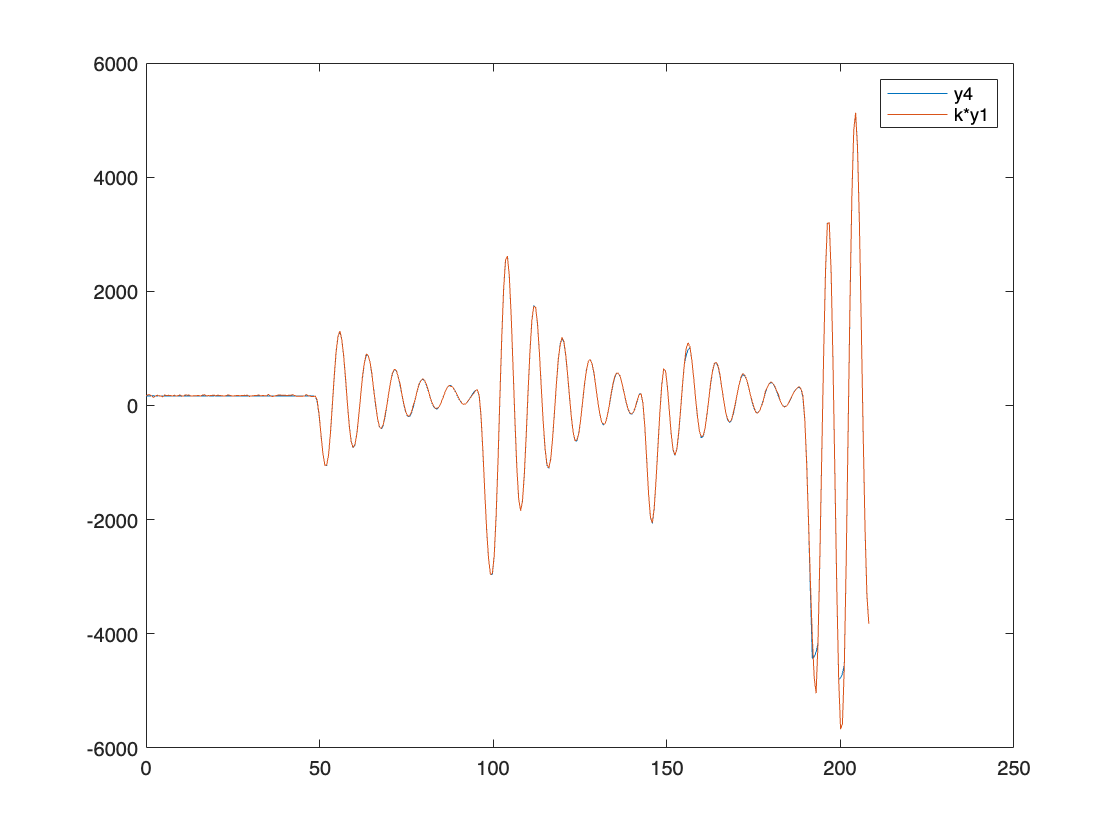


plot(t_minus_delay,y4,t_minus_delay,k2*y1)
legend(["y4", "k*y1"])


rmse1 = rmse(y2+y1,y3);
rmse2 = rmse(k2*y1,y4);
combined_tol1 = tolerance*input_mag*N;
combined_tol2 = tolerance*input_mag*N*k2;
if rmse1 < combined_tol1; success1 = "successful"; else success1 = "not successful"; end
if rmse2 < combined_tol2; success2 = "successful"; else success2 = "not successful"; end

fprintf('linear experiment %s 1/2, RMSE = %0d, tolerance = %0d', success1, rmse1, combined_tol1)

linear experiment successful 1/2, RMSE = 3.633543e+01, tolerance = 196

fprintf('linear experiment %s 2/2, RMSE = %0d, tolerance = %0d', success2, rmse2, combined_tol2)

linear experiment successful 2/2, RMSE = 1.222715e+02, tolerance = 784

if ((rmse1 < combined_tol1) && (rmse2 < combined_tol2))
    fprintf('system is linear')
else
    fprintf('system is nonlinear')
end

system is linear

Generate output data that you will use for identification using your persistently exciting input signal. Also generate new data that you will use for validation.

*Answer**:*

% Use 80% for training and 20% for validation
start_val = round(0.8*N);
uTrain = u(1:start_val-1);
yTrain = y(1:start_val-1);
uVal = u(start_val:end);
yVal = y(start_val:end);

## Part 2: Identification

You will now identify your system using the data that you generated in Part 1. Here, we highly recommend you to use your code from Homework Assignments 3 & 4. It is however **not allowed** to use tools from the `System Identification Toolbox` to identify your system.

Determine the model order. Plot the singular values using the `semilogy` command and motivate your choice of order.

*Answer**:*

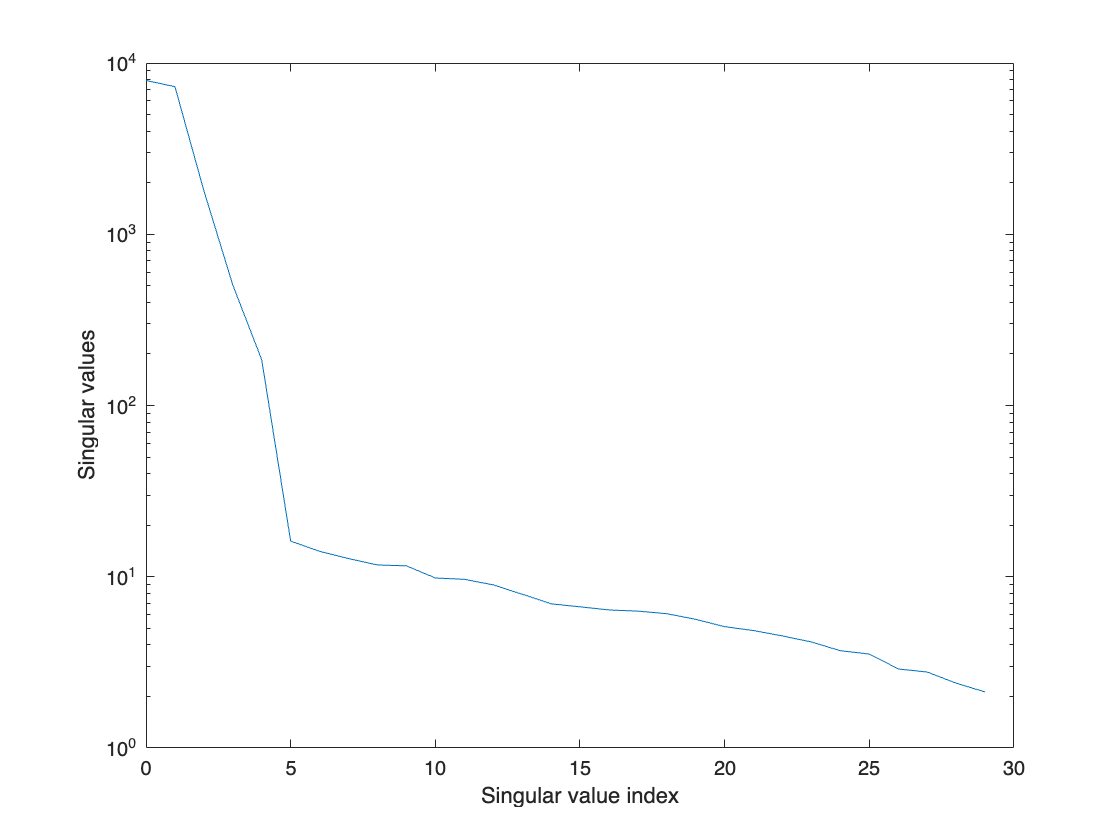

s = 30;
N = length(uTrain) - 2*s + 1;
U_hankel = hankel(uTrain(1:2*s), uTrain(2*s:N+2*s-1)); %hankelmatrix of inputs
Y_hankel = hankel(yTrain(1:2*s), yTrain(2*s:N+2*s-1)); %hankelmatrix of outputs
Uf = U_hankel(s+1:2*s,:);
Up = U_hankel(1:s,:);
Yf = Y_hankel(s+1:2*s,:);
Yp = Y_hankel(1:s,:);
A = [Uf; Up; Yp; Yf];
[Q,R] = qr(A');
L = R';
L_32 = L(3*s+1:end, size(Uf,1)+1:size(Uf,1)+size(Up,1)+size(Yp,1));
[U,S,V] = svd(L_32, 'econ');
singular_vals = diag(S,0);
x_vals = 0:(size(singular_vals,1)-1);

semilogy(x_vals, singular_vals)
xlabel("Singular value index")
ylabel("Singular values")


% see when the singular values drop by one order of magnitude in the plot
% Based on this choose n = 4
n = 4;

Identify the model. You are free to choose the identification method.

*Answer**:*

% Use PO-MOESP method
[A,B,C,D,x0]=pomoesp(uTrain,yTrain,s,n);

## Part 3: Validation

The final step of the system identification cycle is to validate your model. In this part you will validate your identified model using validation data that was **not** used during identification. 

Compare and discuss the VAF for the identification data with the VAF for the validation data.

*Answer**:*

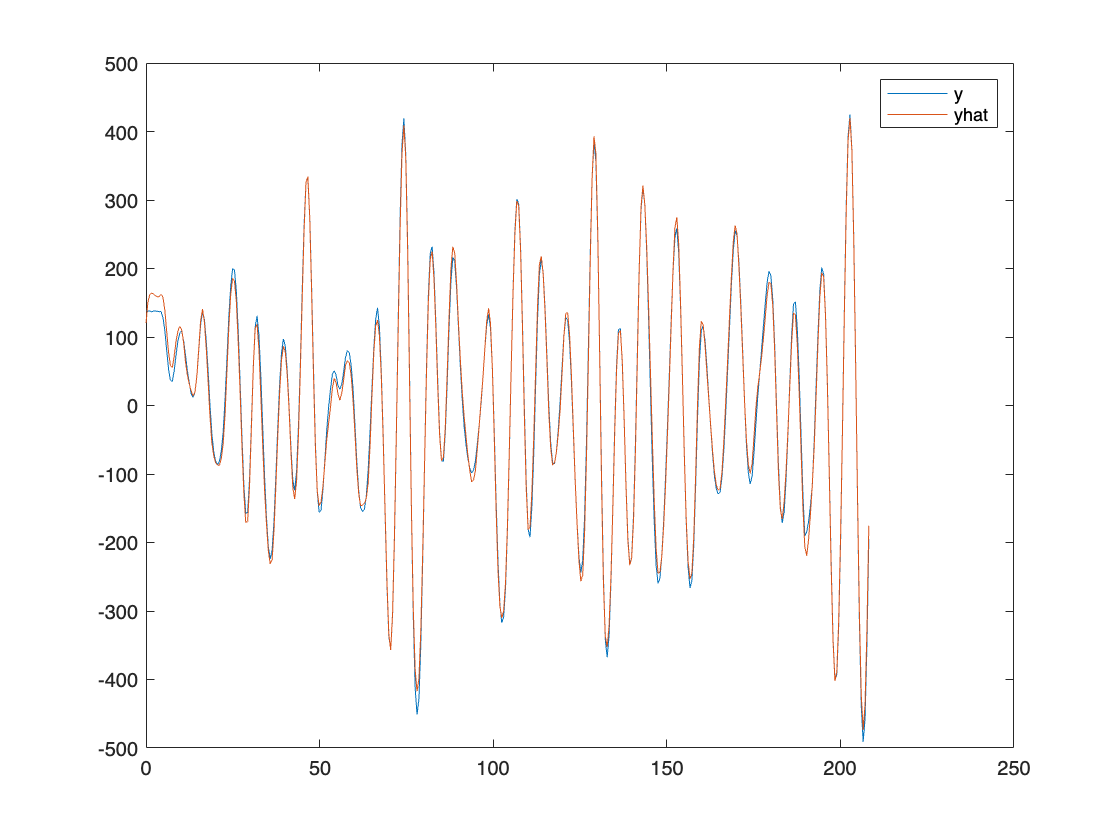

[yhat, xhatTotal] = simsystem(A,B,C,D,x0,u);
yhat = yhat(1:end-delay+1);
yhatTrain = yhat(1:start_val-1);
yhatVal = yhat(start_val:end);

plot(t_minus_delay, y, t_minus_delay, yhat)
legend(["y", "yhat"])


VAFTrain = VAF(yTrain, yhatTrain);
VAFVal = VAF(yVal, yhatVal);

Determine and discuss the auto-correlation of the residuals.

*Answer**:*

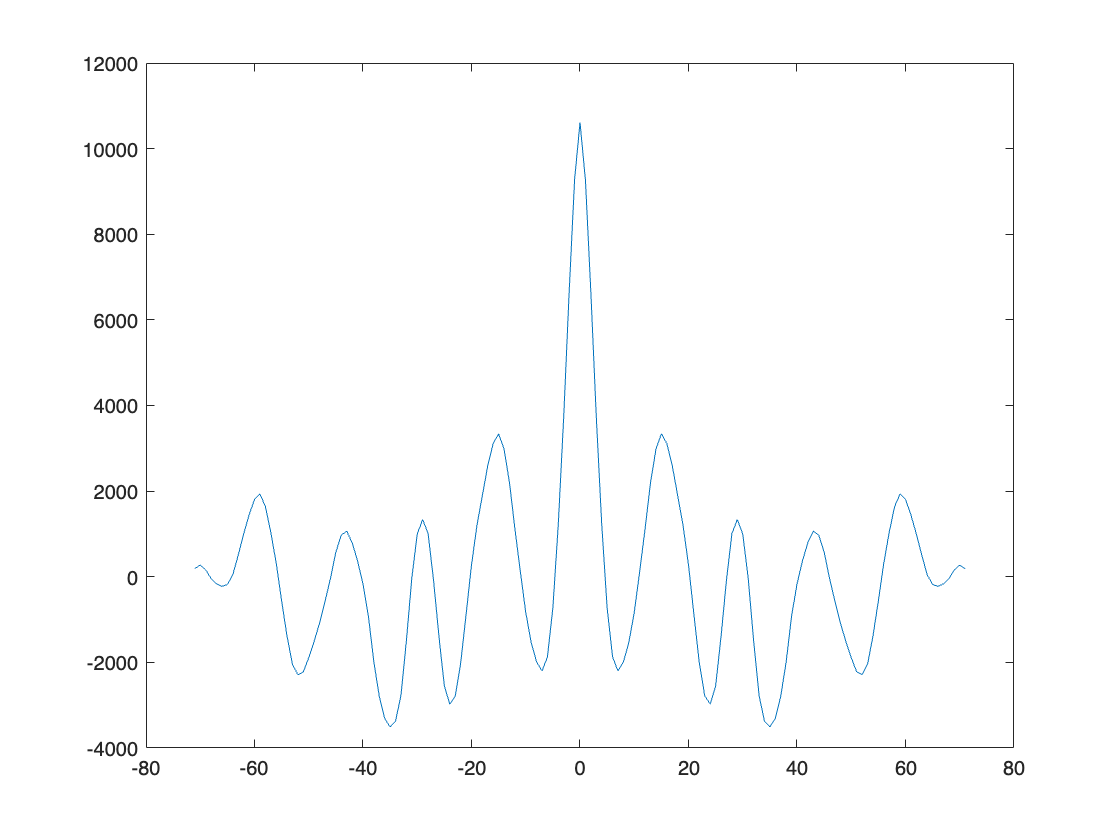

eVal = yVal - yhatVal;
[acf,lags] = xcorr(eVal);

plot(lags,acf)

Determine and discuss the cross-correlation between the residuals and the inputs.

*Answer**:*

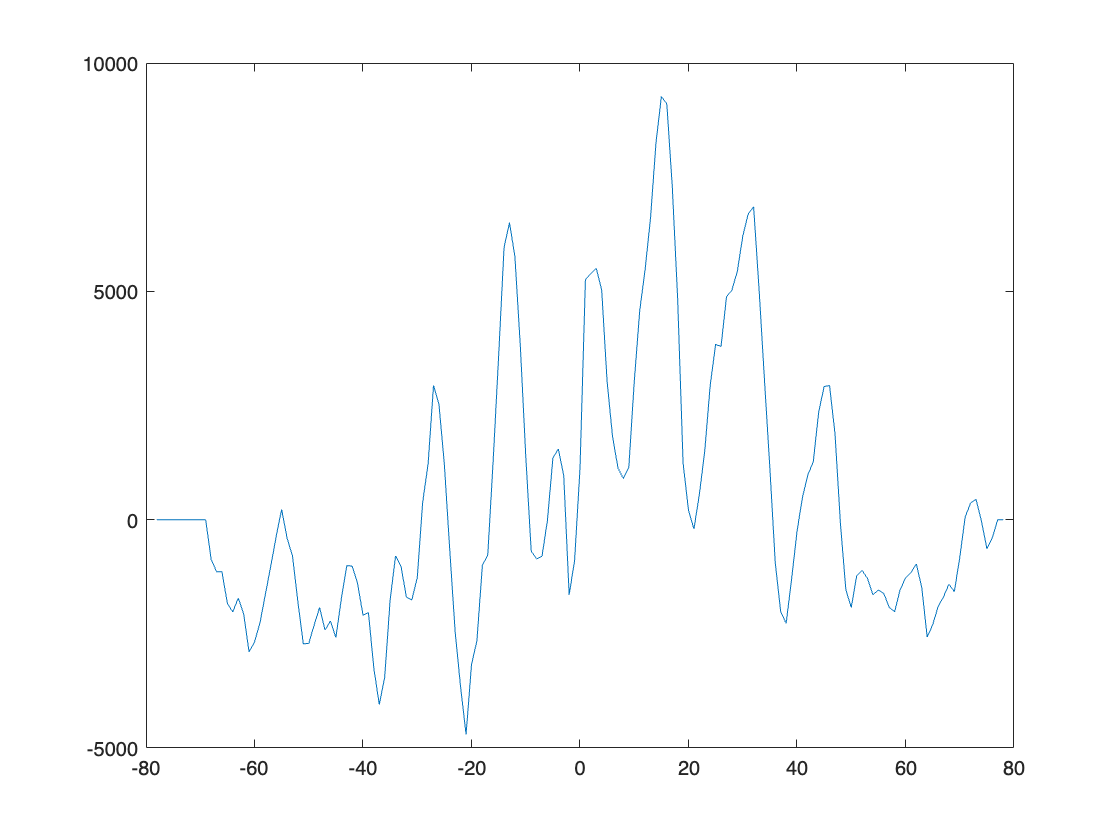

[acf,lags] = xcorr(uVal, eVal);

plot(lags,acf)

**Is your model OK? If not, return to Part 1 and Part 2 for the next iteration. **

## Functions

Implement your functions in this section

### Prediction Error Methods

Implement your PEM functions below 

function [A,B,C,D,x0]=pomoesp(u,y,s,n)
% Function INPUT 
% u         system input (matrix of size N x m)
% y         system output (matrix of size N x l)
% s         block size (scalar)
% n         system order (scalar)
%
% Function OUTPUT
% A         System matrix A (matrix of size n x n)
% B         System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)  

    % Get the Hankel matrices
    N = length(u) - 2*s + 1;
    U_hankel = hankel(u(1:2*s), u(2*s:N+2*s-1)); %hankelmatrix of inputs
    Y_hankel = hankel(y(1:2*s), y(2*s:N+2*s-1)); %hankelmatrix of outputs

    % Get the L32 matrix
    Uf = U_hankel(s+1:2*s,:);
    Up = U_hankel(1:s,:);
    Yf = Y_hankel(s+1:2*s,:);
    Yp = Y_hankel(1:s,:);
    A = [Uf; Up; Yp; Yf];
    [Q,R] = qr(A');
    L = R';
    L_32 = L(3*s+1:end, size(Uf,1)+1:size(Uf,1)+size(Up,1)+size(Yp,1));
    [U,S,V] = svd(L_32, 'econ');

    % Get the A and C matrices
    C = U(1, 1:n);
    A = U(1:s-1, 1:n) \ U(2:end, 1:n);

    % Get x0, B, and D
    phi = [];
    N = size(y,1);
    for k = 1:N 
        middle_sum = zeros(1,n);
        for j = 1:k-1
            middle_sum = middle_sum + kron(u(j), C*A^(k-j-1));
        end
        phi_k = [C*A^(k-1), middle_sum, kron(u(k), 1)];
        phi = [phi; phi_k];
    end
    vec = phi \ y;
    x0 = vec(1:n);
    B  = vec(n+1:2*n);
    D  = vec(2*n+1:end);         

end

### Subspace ID Methods

Implement your Subspace ID functions below 

% Clean the measurement error from y
function y_clean = clean_y(y, input_mag)

    corrupted = find(abs(y) > 20*input_mag);
    x = 1:length(y);
    y_clean = y;

    y_clean(corrupted) = NaN;
    cleaned_vals = interp1(x(~isnan(y_clean)), y_clean(~isnan(y_clean)), corrupted, 'pchip');
    y_clean(corrupted) = cleaned_vals;

end

% Remove delay from y
function y_minus_delay = remove_delay(y, delay)
    y_minus_delay = y(delay:end);
end

% Remove DC offset from y
function y_minus_dc_offset = remove_dc_offset(y)
    % DC offset is the mean of the output
    dc_offset = mean(y);
    % Remove DC offset
    y_minus_dc_offset = y - dc_offset;
end

% Clean, remove delay, and remove DC offset
function filtered_y = filter_y(y, delay, input_mag)
    filtered_y = clean_y(y, input_mag);
    filtered_y = remove_delay(filtered_y, delay);
    filtered_y = remove_dc_offset(filtered_y);
end

function [y,x] = simsystem(A,B,C,D,x0,u)
% Instructions:
% Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% initial condition x(0)
%
%
% Function INPUT
% A system matrix (matrix of size n x n)
% B system matrix (matrix of size n x m)
% C system matrix (matrix of size l x n)
% D system matrix (matrix of size l x m)
% x0 initial state (matrix of size n x one)
% u system input (matrix of size N x m)
%
% Function OUTPUT
% x state of system (matrix of size N x n)
% y system output (matrix of size N x l)

    N = length(u); 
    n = size(A, 1); 
    l = size(C, 1);   

    x = zeros(N,n);
    y = zeros(N,l);

    x(1,:) = x0';

    for i = 1:N
        x(i+1,:) = (A*x(i,:)' + B*u(i))';
        y(i,:) = (C*x(i,:)' + D*u(i))';
    end
    
    x = x(1:N,:);
end

function rmse = RMSE(y,yhat)   
% Function INPUT
% y    measured system output (matrix of size N x l)
% yhat simulated system output (matrix of size N x l)
%
% Function OUTPUT
% RMSE Root Mean Squared Error (scalar)

    squared_diff = (y - yhat).^2;
    mse = mean(squared_diff);
    rmse = sqrt(mse);
end

function vaf = VAF(y,yhat)
% Function INPUT
% y    measured system output (matrix of size N x l)
% yhat simulated system output (matrix of size N x l)
%
% Function OUTPUT
% VAF Variance Accounted For (scalar)
    vaf = (1 - (norm(y - yhat)^2)/norm(y)^2)*100;
end
